%compare deltas from Besset et al. 2019 to Nienhuis et al.2020
%files needed: 'Besset_Deltas.csv' and 'GlobalDeltaData.mat' from Nienhuis et al.2020

load 'GlobalDeltaData.mat';
Big_deltas = readtable('Besset_Deltas.csv');
%[~,DeltaID_Besset] = ismember(delta_name_id, BasinID);

[~,DeltaID_Besset] = ismember(Big_deltas.DELTA, delta_name);

Big_deltas.Aqua = ee.net_aqua(DeltaID_Besset);%GEt original land changes and data
Big_deltas.Pekel = ee.net_pekel(DeltaID_Besset);
Big_deltas.Lat = MouthLat(DeltaID_Besset);
Big_deltas.Lon = MouthLon(DeltaID_Besset);
Big_deltas.Qdist = QRiver_dist(DeltaID_Besset);
Big_deltas.Qprist = QRiver_prist(DeltaID_Besset);
Big_deltas.Qwave = QWave(DeltaID_Besset);
Big_deltas.Qtide = QTide(DeltaID_Besset);

clf
figure
ax1 = subplot(1,2,1)

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


plot(Big_deltas.Aqua, Big_deltas.Net_change_km2_yr,'^','LineWidth',1)
xlabel 'Nienhuis (km^2/yr)'
ylabel 'Besset (km^2/yr)'
h1 = lsline(ax1);
h1.Color = 'r';
grid off
zoom = Big_deltas.Net_change_km2_yr >= -1 & Big_deltas.Net_change_km2_yr <= 1;
text (Big_deltas.Aqua(~zoom), Big_deltas.Net_change_km2_yr(~zoom), Big_deltas.DELTA(~zoom))
box on
axis square
xlim ([-10 20])
ylim ([-10 20])
line ([-10 20], [-10 20],'Color','k','LineStyle','--')
text(10, 18,'1:1 line')
text(-8, 17,'n=48')
text(-8, 16,'R^2=0.038')
text(-8, 15,'p=0.184')
text(-8, 14,'NRMSE=8.3')
text(-8, 13,'ΣNienhuis net= 2.3 km^2/yr')
text(-8, 12,'ΣBesset net= 19.4 km^2/yr')
set(gcf,'color','white')
regression_Big = fitlm(Big_deltas.Aqua, Big_deltas.Net_change_km2_yr)

regression_Big = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat     pValue 
                   ________    _______    _______    _______

    (Intercept)    0.38836     0.49012    0.79237    0.43221
    x1             0.34511     0.25591     1.3485    0.18409


Number of observations: 48, Error degrees of freedom: 46
Root Mean Squared Error: 3.39
R-squared: 0.038,  Adjusted R-Squared 0.0171
F-statistic vs. constant model: 1.82, p-value = 0.184

NRMSEbig = 3.36./mean(Big_deltas.Net_change_km2_yr)

NRMSEbig = 8.2989

NRMSEbig_sd = 3.36./std(Big_deltas.Net_change_km2_yr)

NRMSEbig_sd = 0.9813

sum(Big_deltas.Aqua)

ans = 2.2971

sum(Big_deltas.Net_change_km2_yr)

ans = 19.4340



ax2 = subplot(1,2,2)

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


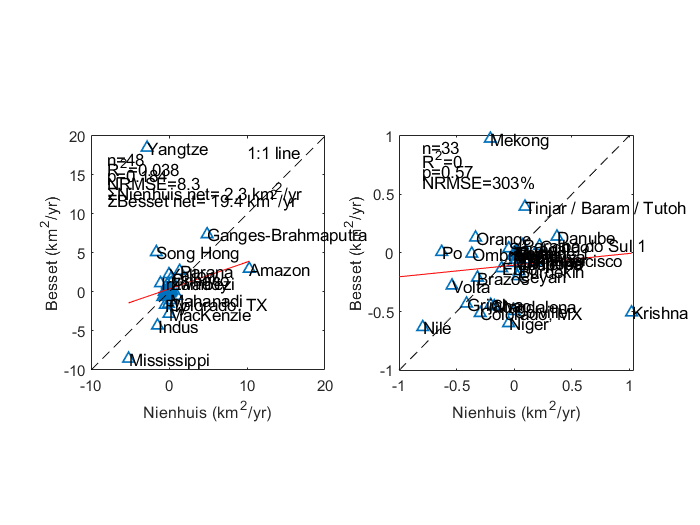

zoom = Big_deltas.Net_change_km2_yr >= -1 & Big_deltas.Net_change_km2_yr <= 1;
plot(Big_deltas.Aqua(zoom), Big_deltas.Net_change_km2_yr(zoom),'^','LineWidth',1)
xlabel 'Nienhuis (km^2/yr)'
ylabel 'Besset (km^2/yr)'
h2 = lsline(ax2);
h2.Color = 'r';
grid off
text (Big_deltas.Aqua(zoom), Big_deltas.Net_change_km2_yr(zoom), Big_deltas.DELTA(zoom))
box on
axis square
xlim ([-1 1.04])
ylim ([-1 1])
line ([-1 1], [-1 1],'Color','k','LineStyle','--')

text(-0.8, 0.9,'n=33')
text(-0.8, 0.8,'R^2=0')
text(-0.8, 0.7,'p=0.57')
text(-0.8, 0.6,'NRMSE=303%')


set(gcf,'color','white')

regression_Big_zoom = fitlm(Big_deltas.Aqua(zoom), Big_deltas.Net_change_km2_yr(zoom))

regression_Big_zoom = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue 
                   ________    ________    _______    _______

    (Intercept)     -0.1032    0.055846     -1.848    0.07417
    x1             0.099254      0.1753    0.56621    0.57533


Number of observations: 33, Error degrees of freedom: 31
Root Mean Squared Error: 0.314
R-squared: 0.0102,  Adjusted R-Squared -0.0217
F-statistic vs. constant model: 0.321, p-value = 0.575

NRMSEbigzoom = 0.333./mean(Big_deltas.Net_change_km2_yr(zoom))*-1

NRMSEbigzoom = 3.0306

NRMSEbigzoom = 0.333./std(Big_deltas.Net_change_km2_yr(zoom))

NRMSEbigzoom = 1.0734


sum(Big_deltas.Net_change_km2_yr(zoom))

ans = -3.6260



sum(Big_deltas.Net_change_km2_yr)

ans = 19.4340

sum(Big_deltas.Aqua)

ans = 2.2971